# Modeling and Optimizing a Battery Charging Profile

In this project, you will use MATLAB to model a battery charging profile. You will fit real lithium‑ion battery data in MATLAB, compute energy transfer through numerical integration, and analyze key performance characteristics such as charge‑rate behavior and efficiency losses.

Use this Live Script as a template to get started on your project solution. You may include helper functions at the bottom of this document or as separate files. For a tutorial on how to use Live Scripts, check out this [video](https://www.youtube.com/watch?v=hUXTyPYRidM).

**Suggested Tasks**

- Given data for a lithium-ion battery charging profile, use MATLAB to fit the equation for voltage provided in the Project Description.

- Plot the following curves: voltage vs. time, current vs. time, and power vs. time.

- Use integration to compute the total energy delivered to the battery (area under power-time curve).

- Analyze the rate of voltage change at different intervals (calculate derivatives), compute the time to reach 80% and 100% charge, and compute the energy lost due to resistance.

## Break Down the Problem

In the space below, define the problem statement:

List the requirements, constraints, and success criteria for the project:

What is your proposed solution?

List the steps you will need to take to achieve your proposed solution:

What challenges do you face in the process of achieving the solution?

## Task 1: Fit the voltage equation to a lithium-ion battery profile

Given real time-series voltage data for a lithium-ion battery, use MATLAB Curve Fitting Toolbox to fit the equation $V\left(t\right)=V_{\max } \left(1-e^{-\frac{t}{\mathrm{RC}}} \right)$ and model the battery charging profile as a simple RC-circuit analog.

Load MathWorks example lithium-ion batteries data by following the steps [here](https://www.mathworks.com/help/predmaint/ug/data-analysis-and-feature-extraction-for-battery-raw-cycling-data.html). The page also includes information about the dataset, how the data was recorded, and the battery's maximum voltage.

**Note**: The battery from this example dataset has been cycled to failure (charged and discharged repeatedly). For this project, you may choose to use data from a single cycle and focus only on the period of time within a cycle that the battery is being charged. The battery is fully charged at 3.6V. This example battery uses a dynamic fast charging profile, but for this project, you will attempt to model the charging profile using a simple exponential capacitor charging equation.

Then, follow the workflow outlined in the [documentation](https://www.mathworks.com/help/curvefit/fit.html) to fit the voltage equation to your selected data. Plot the data and fitted curve in the same figure and, finally, print the goodness-of-fit statistics.

% Insert your code in the spaces below (or make use of helper functions and indicate where
% they can be found). Ensure your code is well-documented.


% STEP 1a
% Load the example battery dataset, plus view of first 5 lines as preview
dataFile = matlab.internal.examples.downloadSupportFile("predmaint","batteryagingdata/singlecell/v1/singleCellLifeTimeData.zip");
unzip(dataFile)
load("singleCellLifeTimeData.mat")
head(data, 5)

    Data_Point    Test_Time          DateTime          Step_Time    Step_Index    Cycle_Index    Current    Voltage    Charge_Capacity    Discharge_Capacity    Charge_Energy    Discharge_Energy       dV/dt       Internal_Resistance    Temperature
    __________    _________    ____________________    _________    __________    ___________    _______    _______    _______________    __________________    _____________    ________________    ___________    ___________________    ___________

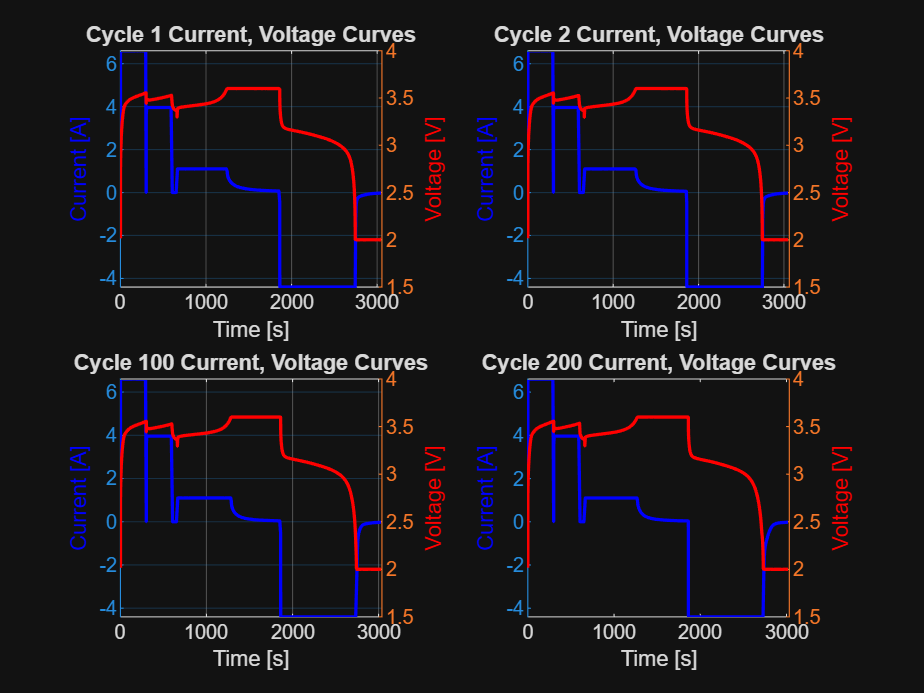



% STEP 1b
% Battery data sample evaluation: observing differences in the charging cycles over
% a select sample of cycles (just for team reference, this is not part of
% the task requirements/steps.

% multi-subplot generation to compare cycles 1, 2, 100, 200, 300, 400, 500, 600, 700, 800, 875, and 876
sample_cycles_set1 = [1, 2, 100, 200];
sample_cycles_set2 = 300:100:600;
sample_cycles_set3 = [700, 800, 875, 876];

figure;
for index = 1:length(sample_cycles_set1)
grid on;
subplot(2, 2, index)
cycleData = data(data.Cycle_Index == sample_cycles_set1(index), :);
cycleData.DateTime = seconds(cycleData.DateTime - cycleData.DateTime(1));
yyaxis left;
gca.YColor = 'blue';
plot(cycleData.DateTime,cycleData.Current, '-b', 'LineWidth', 1.5);
ylabel('Current [A]', 'Color', 'blue');
yyaxis right;
gca.YColor = 'red';
plot(cycleData.DateTime,cycleData.Voltage, '-r', 'LineWidth', 1.5);
ylabel('Voltage [V]', 'Color', 'red');
xlabel("Time [s]");
title(sprintf('Cycle %d Current, Voltage Curves', sample_cycles_set1(index)))
end

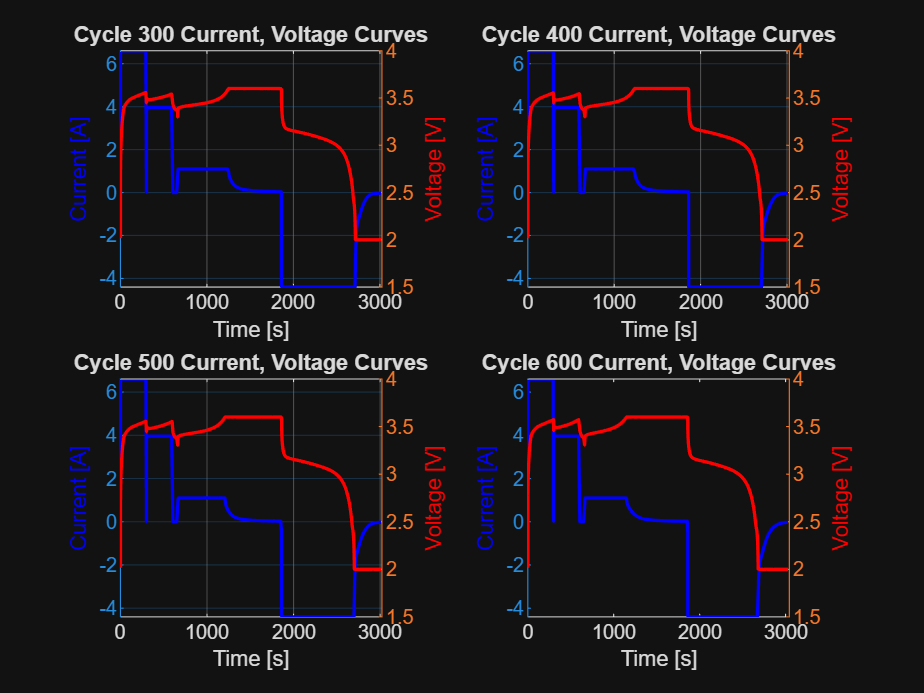


figure;
for index = 1:length(sample_cycles_set2)
grid on;
subplot(2, 2, index)
cycleData = data(data.Cycle_Index == sample_cycles_set2(index), :);
cycleData.DateTime = seconds(cycleData.DateTime - cycleData.DateTime(1));
yyaxis left;
gca.YColor = 'blue';
plot(cycleData.DateTime,cycleData.Current, '-b', 'LineWidth', 1.5);
ylabel('Current [A]', 'Color', 'blue');
yyaxis right;
gca.YColor = 'red';
plot(cycleData.DateTime,cycleData.Voltage, '-r', 'LineWidth', 1.5);
ylabel('Voltage [V]', 'Color', 'red');
xlabel("Time [s]");
title(sprintf('Cycle %d Current, Voltage Curves', sample_cycles_set2(index)))
end

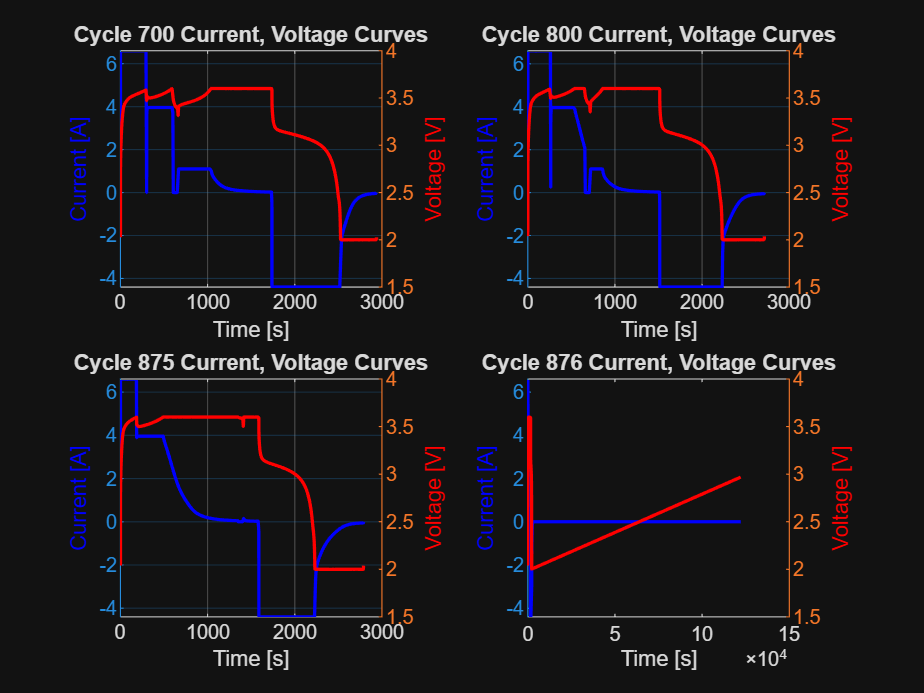


figure;
for index = 1:length(sample_cycles_set3)
grid on;
subplot(2, 2, index)
cycleData = data(data.Cycle_Index == sample_cycles_set3(index), :);
cycleData.DateTime = seconds(cycleData.DateTime - cycleData.DateTime(1));
yyaxis left;
gca.YColor = 'blue';
plot(cycleData.DateTime,cycleData.Current, '-b', 'LineWidth', 1.5);
ylabel('Current [A]', 'Color', 'blue');
yyaxis right;
gca.YColor = 'red';
plot(cycleData.DateTime,cycleData.Voltage, '-r', 'LineWidth', 1.5);
ylabel('Voltage [V]', 'Color', 'red');
xlabel("Time [s]");
title(sprintf('Cycle %d Current, Voltage Curves', sample_cycles_set3(index)))
end

% NOTE: the charging-discharging cycles start to degrade near the end...
% choosing CYCLE 1 for the next part because it doesn't have as many...
% discontinuities/gaps as some of the other randomly sampled cycle graphs.


% STEP 2
% Pre-process the data to focus on a single cycle, and the period of time
% within that cycle that the battery was being charged

% Single cycle to focus on: CYCLE 1, code below is just from following the...
% 'MathWorks example Li-ion batteries data'
bParser = batteryTestDataParser(data);
bParser.CurrentVariable = 'Current';
bParser.VoltageVariable= "Voltage";
bParser.TimeVariable = "DateTime";
bParser.CycleIndexVariable = 'Cycle_Index';
bParser.StepIndexVariable = 'Step_Index';

% generate table formatting
segmentedRawDataTable = segmentData(bParser);
head(segmentedRawDataTable,5)

    Data_Point    Test_Time          DateTime          Step_Time    Step_Index    Cycle_Index    Current    Voltage    Charge_Capacity    Discharge_Capacity    Charge_Energy    Discharge_Energy       dV/dt       Internal_Resistance    Temperature    CyclingModes    CyclingPhases    IsValid
    __________    _________    ____________________    _________    __________    ___________    _______    _______    _______________    __________________    _____________    ________________    <s



% STEP 3
% Follow the provided workflow to fit the voltage equation to your selected
% data.
% HINT: Vmax is known, so the only unknown in the equation is RC (also
% known as tau, the RC time constant - it is equivalent to the time it takes
% for a capacitor to reach ~63.2% of its max voltage).
% When you are fitting the curve to the data, you are essentially estimating
% the unknown parameter, tau.

% All the stuff below is just parsing the data to CONFIRM that Vmax ~= 3.6 Volts
% verify what variable 'dV/dt' is actually called
data.Properties.VariableNames

ans = 1×15 cell array
    {'Data_Point'}    {'Test_Time'}    {'DateTime'}    {'Step_Time'}    {'Step_Index'}    {'Cycle_Index'}    {'Current'}    {'Voltage'}    {'Charge_Capacity'}    {'Discharge_Capacity'}    {'Charge_Energy'}    {'Discharge_Energy'}    {'dV/dt'}    {'Internal_Resistance'}    {'Temperature'}



% change var name of "dV/dt" because it isn't syntax-friendly to
% MATLAB ("data.dV/dt" keeps giving error")
data = renamevars(data, "dV/dt", "dVdt");

% boolean array of where dV/dt ~= 0, only in region of Vmax, only for cycle
% 1
mask = data.Cycle_Index == 1 & data.Voltage > 3.2 & abs(data.dVdt) < 0.01;

% use boolean array to analyze that flat region near the theoretical Vmax,
% in "Cycle 1 Current, Voltage Curves" graph
V_maxes_ls = data.Voltage(mask);

% temporarily displayed command: 'disp(Vmaxes_ls)', which is a list of Vmaxes
experimental_V_max = max(V_maxes_ls);

% just verifying if experimental_V_max is close to V_max = 3.6 Volts
disp(experimental_V_max)

    3.6004





% STEP 4
% Plot the data and the fitted curve in the same figure.
% Using curve fitter! 't' is time (x-axis), 'V' is Voltage (y-axis), ...
% V_max is given 3.6 value.
% 'T' will be used to represent tau, the RC time constant (T = RC)

% checking data type, data values
data(data.Cycle_Index == 1, :)

ans = 1078×15 table
    Data_Point    Test_Time          DateTime          Step_Time    Step_Index    Cycle_Index    Current    Voltage    Charge_Capacity    Discharge_Capacity    Charge_Energy    Discharge_Energy       dVdt        Internal_Resistance    Temperature
    __________    _________    ____________________    _________    __________    ___________    _______    _______    _______________    __________________    _____________    ________________    ___________    ___________________    


charging_data_only = data(data.Cycle_Index == 1 & data.Current >= 0, :);

% variables / parameters of (custom) fitting equation
t = seconds(charging_data_only.DateTime - charging_data_only.DateTime(1));
V = charging_data_only.Voltage;
V_max = 3.6;

% "optimization" of tau value?
model1 = @(T, t) V_max * (1 - exp(-t / T));

% placeholder guess for tau (T)
T0 = 1000;
T = lsqcurvefit(model1, T0, t, V);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


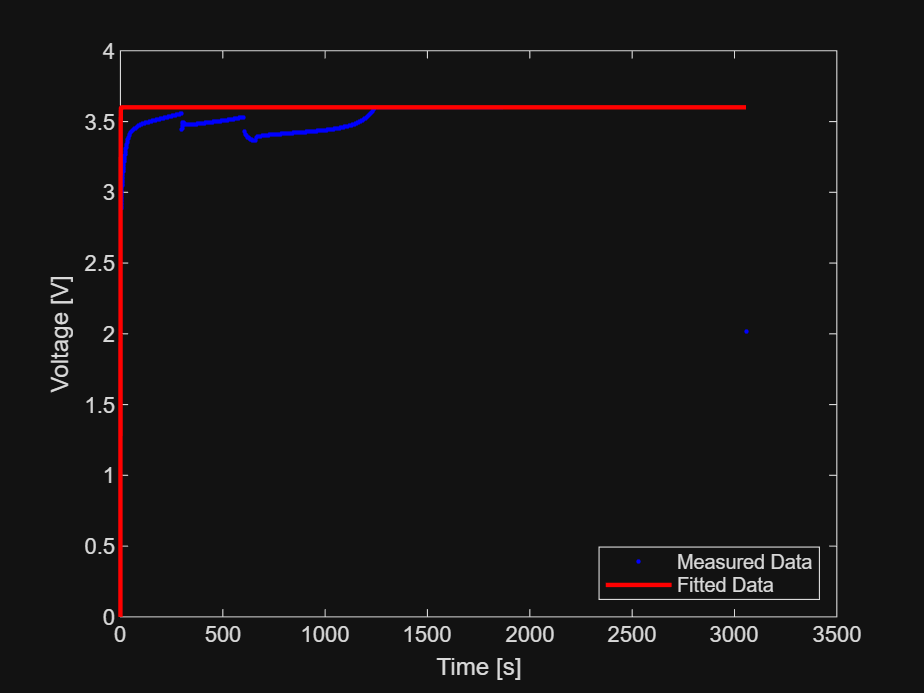


V_fit = model1(T, t);

% plotting both parsed data AND fitted data
figure
plot(t, V, 'b.')
hold on
plot(t, V_fit, 'r', 'LineWidth', 2)

% final graph labels + legend
xlabel('Time [s]')
ylabel('Voltage [V]')
legend('Measured Data', 'Fitted Data', 'Location', 'southeast')

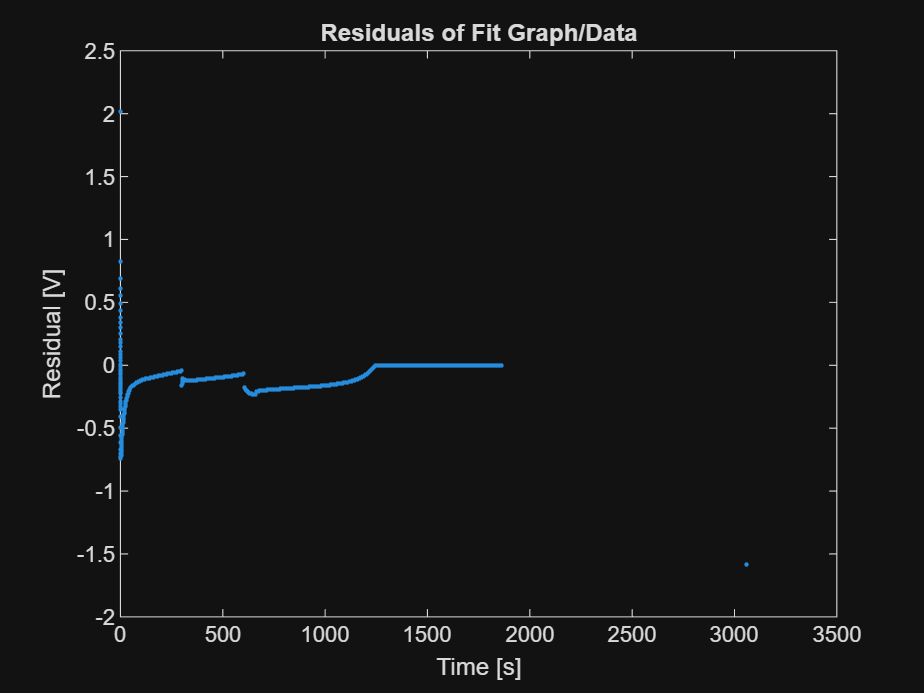



% STEP 5
% Calc + display the goodness-of-fit statistics.
residuals = V - V_fit;

sum_of_squared_errors = sum(residuals.^2);

root_mean_squared_error = sqrt(mean(residuals.^2));

% next, use 'sum_of_squared_errors' and calc 'total sum of squares'
% to get R^2 (common statistical value)
total_sum_of_squares = sum((V - mean(V)).^2);

R2_value = 1 - sum_of_squared_errors / total_sum_of_squares;

% not sure if need to plot residuals because there's a lot of them...
% didn't realize it was an array
figure
grid on
plot(t, residuals, '.')
xlabel('Time [s]')
ylabel('Residual [V]')
title('Residuals of Fit Graph/Data')


% easy display statements
disp(residuals)

    2.0153
    0.8273
    0.6876
    0.6132
    0.5574
    0.4934
    0.4388
    0.3832
    0.3382
    0.3026
    0.2486
    0.2057
    0.1784
    0.1484
    0.1127
    0.0829
    0.0588
    0.0369
    0.0095
   -0.0131
   -0.0309
   -0.0535
   -0.0615
   -0.0765
   -0.0958
   -0.1104
   -0.1260
   -0.1444
   -0.1527
   -0.1702
   -0.1849
   -0.2002
   -0.2180
   -0.2283
   -0.2591
   -0.2896
   -0.3012
   -0.3290
   -0.3538
   -0.4070
   -0.4937
   -0.5577
   -0.6164
   -0.6660
   -0.7013
   -0.7225
   -0.7350
   -0.7404
   -0.7406
   -0.7367
   -0.7308
   -0.7235
   -0.7235
   -0.7151
   -0.7059
   -0.6964
   -0.6865
   -0.6764
   -0.6664
   -0.6561
   -0.6459
   -0.6359
   -0.6258
   -0.6158
   -0.6158
   -0.6057
   -0.5955
   -0.5852
   -0.5748
   -0.5648
   -0.5543
   -0.5442
   -0.5342
   -0.5239
   -0.5137
   -0.5035
   -0.4932
   -0.4832
   -0.4731
   -0.4629
   -0.4525
   -0.4423
   -0.4321
   -0.4321
   -0.4220
   -0.4119
   -0.4018
   -0.3918
   -0.3918
   -0.3817
   -0.3717

disp(sum_of_squared_errors)

   36.5655



disp(root_mean_squared_error)

    0.2400



disp(R2_value)

    0.4199



## Task 2: Plot the electrical terms that express how energy moves in a circuit

To visualize the battery's charging policy, write code to visualize the current, voltage, and power measurements for one charging cycle. Present the visualization as one figure with three subplots, one each for:

- Voltage vs. time

- Current vs. time

- Power vs. time

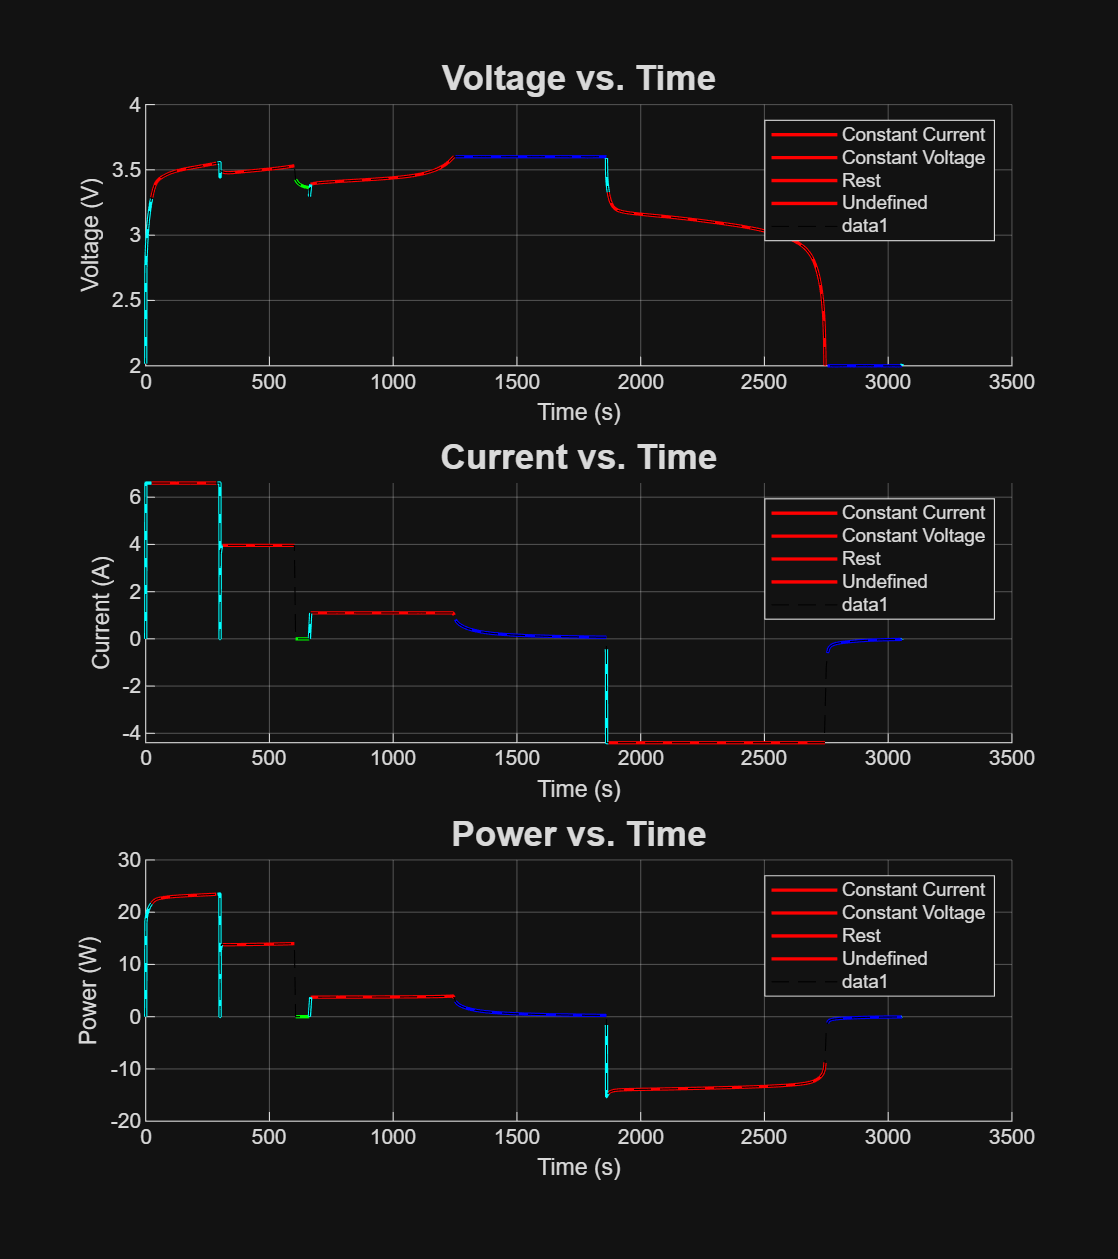

% Insert your code in the spaces below (or make use of helper functions and
% indicate where they can be found). Ensure your code is well-documented.

% STEP 1
% Create a figure handle and initialize the first subplot. Plot voltage vs.
% time.

%chosen cycle I want to focus on (has been the standard so far
cycle_number = 1;

%getting only the segmented data for the chosen cycle
cycle_data = segmentedRawDataTable(segmentedRawDataTable.Cycle_Index == cycle_number,:);

%resets time so the cycle data starts at the 0 second mark
cycle_data.DateTime = seconds(cycle_data.DateTime - cycle_data.DateTime(1));

%defining variables to make them easier to input
time = cycle_data.DateTime;
current = cycle_data.Current;
voltage = cycle_data.Voltage;


%creating figure
figure_handle = figure('Name', 'Battercy Charging Profile', 'Position', [200,100,800,900]);

%creating a 3 row by 1 column matrix for each of the graphs
% (Voltage v time, Current v time, and power v time, 
% this one is first subplot indicated by the third 

subplot(3, 1, 1) 

%importing from the helper function(CycleModes) so we don't have to keep
%rewriting the same function over again
plotcycle_modes(time, voltage, cycle_data.CyclingModes) 

%also plotting the original function for Voltage v time on the same graph
%(under it where it is black and dotted line) (idk if this is needed)
hold on
plot(time, voltage, 'k', 'LineStyle','--')
hold off

%titling the first subplot
title('Voltage vs. Time', 'FontSize', 16)
xlabel('Time (s)')
ylabel('Voltage (V)')


% STEP 2
% Use a second subplot to plot current vs. time.

%repeating the same steps as done in step 1
subplot(3,1,2)
plotcycle_modes(time, current, cycle_data.CyclingModes)

hold on
plot(time, current, 'k', 'LineStyle','--')
hold off


title('Current vs. Time', 'FontSize', 16)
xlabel('Time (s)')
ylabel('Current (A)')

%I DONT KNOW WHY EVERYTHING IN THE LEGEND SHOWS RED

% STEP 3
% Use a third subplot to plot power vs time.
% Hint: P = I * V where I is current in amps. You will first
% need to compute power before you can create this plot.

%calculating power using P=IV (use . since multiplying rows in matrix)
power = current .*voltage;


## Task 3: Compute analytical results

To get started on using MATLAB for numerical integration and differentiation, start with this [doc page](https://www.mathworks.com/help/matlab/numerical-integration-and-differentiation.html?s_tid=CRUX_lftnav).

- Conduct a rate-of-change analysis by computing the derivative at key intervals in the voltage data

- Compute the time required to reach 80% and 100% charge

- Compute the total energy delivered to the battery by using integration to calculate the area under the power-time curve.

- Estimate the resistive energy loss

- Save the results to a summary table.

% Insert your code in the spaces below (or make use of helper functions and indicate where
% they can be found). Ensure your code is well-documented.

% STEP 1: Compute the rate of voltage change at different key time
% intervals. This helps you mathematically characterize the battery's
% charging profile and is more reliable than simply eyeballing the voltage
% vs. time plot. 
% Optional: plot the points of notable transitions in charging dynamics in
% the voltage vs. time plot generated above
% Hint: explore using the gradient function

% STEP 2: Compute the time required to reach 80% charge and 100% charge

% STEP 3: Use integration to calculate the area under the power-time curve.
% This represents the total energy delivered to the battery during charging.
% Hint: explore using the trapz function

% STEP 4: Estimate the resistive energy loss. 
% Hint: use Joule's heating formula (P = I^2 * R) to estimate power loss in
% watts. The energy loss is given as E = P * t, where t is time in seconds
% and energy is in joules.

% STEP 5: Save results to a summary table. Display the table.



## Interpretation of Results

Summarize your findings by interpreting their physical/engineering meaning (for example, why would engineers want to compute the analytical results in Task 3?):

What are some limitations of your work?

What are practical next steps?